# Model Microspeaker

This example shows a general model of a microspeaker mounted on a infinite baffel. Microspeakers are often used in headphone applications or other miniature listening devices. They have similar technology as the traditional loudspeaker. However, it contains additional acoustic component as the basic structure is different than loudspeakers.  This model breaks down the details of a typical microspeaker. A composite `Microspeaker` block is included within the acoustic domain library. 

## Open the Model

Open the microspeaker model.

model = "Microspeaker";
open_system(model);

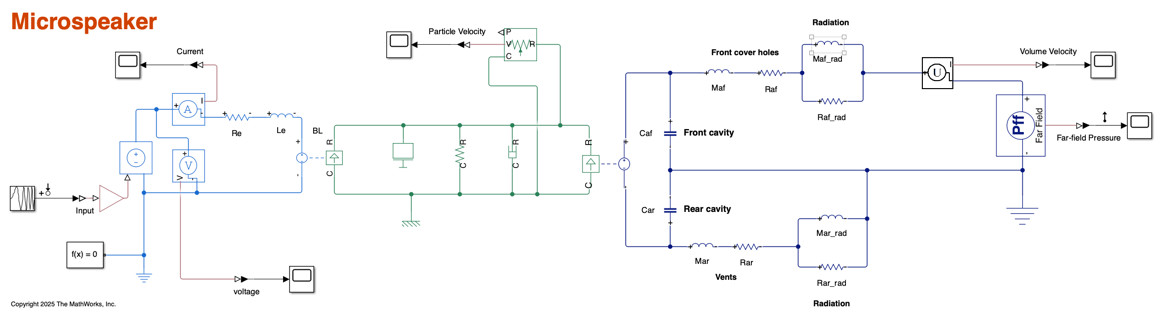

## Linearize the Model

This example sets the input perturbation point and output measurement point for analysis to be done in the frequency domain instead of time domain. Extracting the real time simulation outputs and performing Fourier Transform will also returns the same results.

Set the model linearizing points.

io(1) = linio("Microspeaker/Chirp Signal",1, "input");              % input perturbation
io(2) = linio("Microspeaker/Far-field Pressure",1, "output");       % output measurement

Use the `linearize` function to linearize the model and the `bode` function to extract the magnitude, phase, and frequency information. 

linsys = linearize(model,io);       % linearize model
[mag, ~, wout] = bode(linsys);      % extract results

Note that the frequency information is in rad/s. Divide by $2\pi $to convert into Hz. The sound pressure level in dB is given by:


$$\textrm{dBSPL}=20\;\log \;\left(\frac{p_{\textrm{rms}} }{p_{\textrm{ref}} }\right)$$


where the reference pressure in air is $p_{ref}=20\mu Pa$.

p_ref = 20e-6;          % reference pressure in air (Pa)
freq = wout./(2*pi);    % convert radiance to frequency
SPL = 20.*log10(mag(:)./p_ref);         % calculate dBSPL

Plot the results.

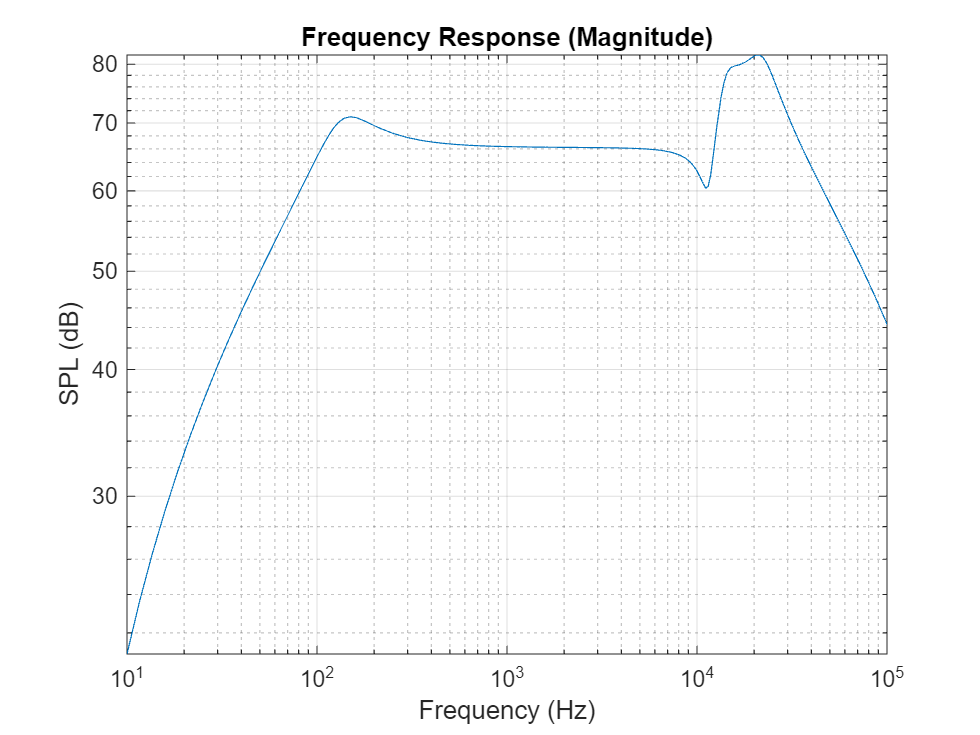

figure(1)
loglog(freq, SPL);
xlim([10 100e3]);
title("Frequency Response (Magnitude)");
xlabel("Frequency (Hz)");
ylabel("SPL (dB)");
grid on
hold on

## Increase Rear Cavity

The rear cavity is increased by a factor 10 and the result is compared to the original state. In this model, the rear cavity is assumed to be a simple air compliance presented as a capacitor. The resonance frequency related to the rear cavity can be given by the following equation:


$$f=\sqrt{\frac{1\;\;}{\;mC}}$$


where m is the related mass from the system and C is the compliance of the rear cavity. The compliance from the rear cavity can be give by:


$$C=\frac{\;V}{\;\rho c^{2\;} }$$


where $\rho \;$is the air density and $c$ is the speed of sound in air

The equation shows that the compliance is proportional to the volume. Thus, as the volume increased by a factor of 10, the compliance also increased by a factor of 10. The related resonanace freqeucny is inversely proportional to the compliance. As a result, one can expect the peaks introduced by the rear cavity compliance would shift towards lower frequency.

path = model + "/Car";
set_param(path,"c", "7.1403e-12");

Linearize the modified model.

linsys = linearize(model,io);           % linearize model
[mag, ~, wout] = bode(linsys);      % extract results
freq = wout./(2*pi);                    % convert radiance to frequency
SPL = 20.*log10(mag(:)./p_ref);         % calculate dBSPL

Plot the results.

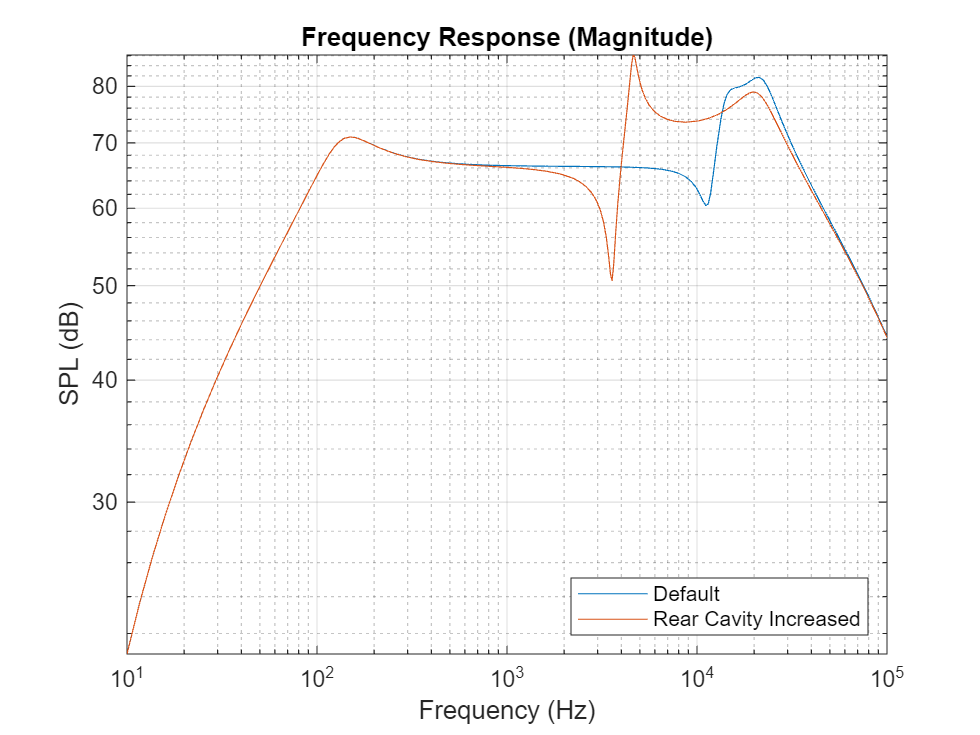

figure(1)
loglog(freq, SPL);
xlim([10 100e3]);
title("Frequency Response (Magnitude)");
xlabel("Frequency (Hz)");
ylabel("SPL (dB)");
legend("Default", "Rear Cavity Increased", "Location", "southeast");
grid on
hold on

Restore the value.

set_param(path,"c", "7.1403e-13");   

## Decrease Front Cavity

The front cavity is decreased by a factor 10 and the result is compared to the original state. In this model, the front cavity is assumed to be a simple air compliance presented as a capacitor. The compliance from the front cavity can be give by:


$$C=\frac{\;V}{\;\rho c^{2\;} }$$


where $\rho \;$is the air density and $c$ is the speed of sound in air

The equation shows that the compliance is proportional to the volume. Thus, as the volume decreased by a factor of 10, the compliance also decreased by a factor of 10. 

The impedance form of a compliance is given by:


$$Z=\frac{\;1}{\;j\omega \;C}$$


At low frequencies, the impedance of the compliance is infinitely large, and the circuit can be treated as an open and no flows will go through. However, as the frequency increases, the impedance rolls off in the slope of $\frac{\;1}{\;\;C}$. Thus, if the compliance decreased, the high frequency roll-off is pushed towards higher frequencies and more low frequency is preserved. As the front cavity decreases, one can expect the high frequency roll off stats later than the original form. 

path = model+"/Caf";
set_param(path,"c", "7.197e-14");    

Linearize the modified model.

linsys = linearize(model,io);       % linearize model
[mag, ~, wout] = bode(linsys);      % extract results
freq = wout./(2*pi);                % convert radiance to frequency
SPL = 20.*log10(mag(:)./p_ref);     % calculate dBSPL

Plot the results.

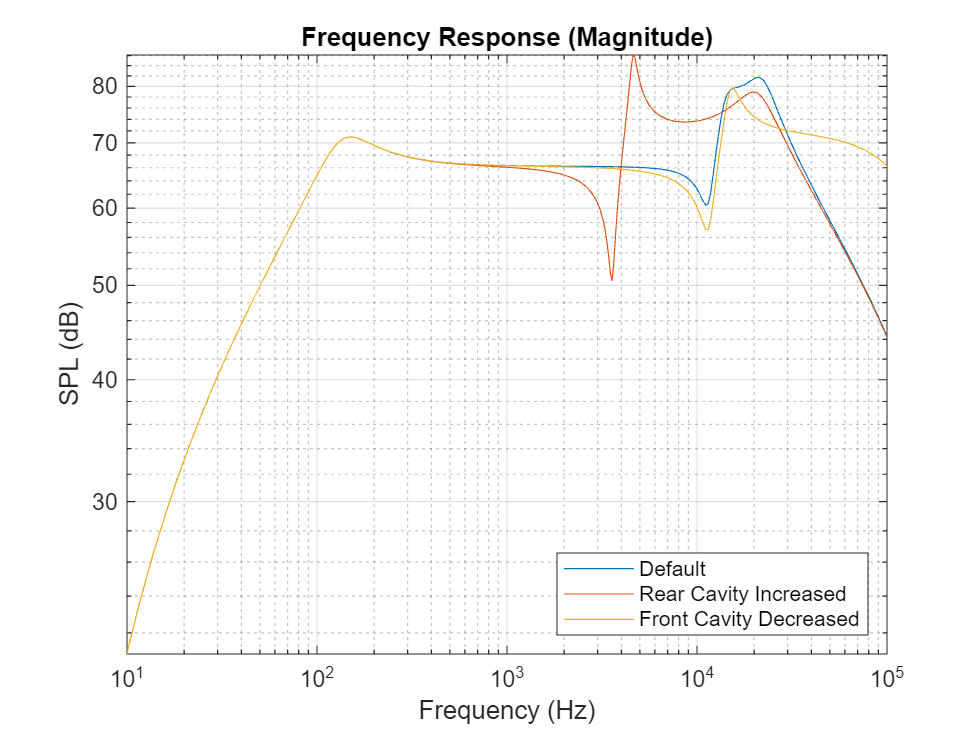

figure(1)
loglog(freq, SPL);
xlim([10 100e3]);
% ylim([70 140]);
title("Frequency Response (Magnitude)");
xlabel("Frequency (Hz)");
ylabel("SPL (dB)");
legend("Default", "Rear Cavity Increased", "Front Cavity Decreased", "Location", "southeast");
grid on
hold on

Restore the value.

set_param(path,"c", "7.197e-13");  

## Reduce Front Cover Holes

The holes on the front cover can be modeled as an inductor and resistor connected in series. The inductor and resistor represent the air mass and air resistance inside the small tube respectively. For multiple holes with identical dimensions, they are stacked in parallel. The total air mas and air resistance from the holes can be lumped into single inductor and resistor. The respective values are given by the following equations:


$$M_a =\frac{4\rho l_{hole} }{3A_{hole} N_{hole} }$$



$$R_a =\frac{8\pi \rho \nu l_{hole} }{A_{hole}^2 N_{hole} }$$


where

$l_{hole}$ is the length of the individual hole

$A_{hole}$ is the cross sectional area of the individual hole

$N_{hole}$ is the total number of holes

$\rho$ is the air density

$\nu$ is the kinematic viscosity of air

Both reducing the cross sectional area or the number holes are quivalent to increasing the total air mass contributed by the front cover holes. $A_{hole}$ and $N_{hole}$ are both incersely proportional to the total mass.

The resonance frequency related to the holes can be given by the following equation:


$$f=\sqrt{\frac{1\;\;}{\;mC}}$$


where m is the total mass and C is the related compliance from the system.

The related resonanace freqeucny is inversely proportional to the mass. As a result, one can expect the peaks introduced by the front cover holes air mass would shift towards lower frequency.

path1 = model+"/Maf";
set_param(path1,"m", "17.118*20");         % set parameter to decrease the rear cavity by a factor of 0.01

Linearize the modified model.

linsys = linearize(model,io);           % linearize model
[mag, ~, wout] = bode(linsys);      % extract results
freq = wout./(2*pi);                    % convert radiance to frequency
SPL = 20.*log10(mag(:)./p_ref);         % calculate dBSPL

Plot the results.

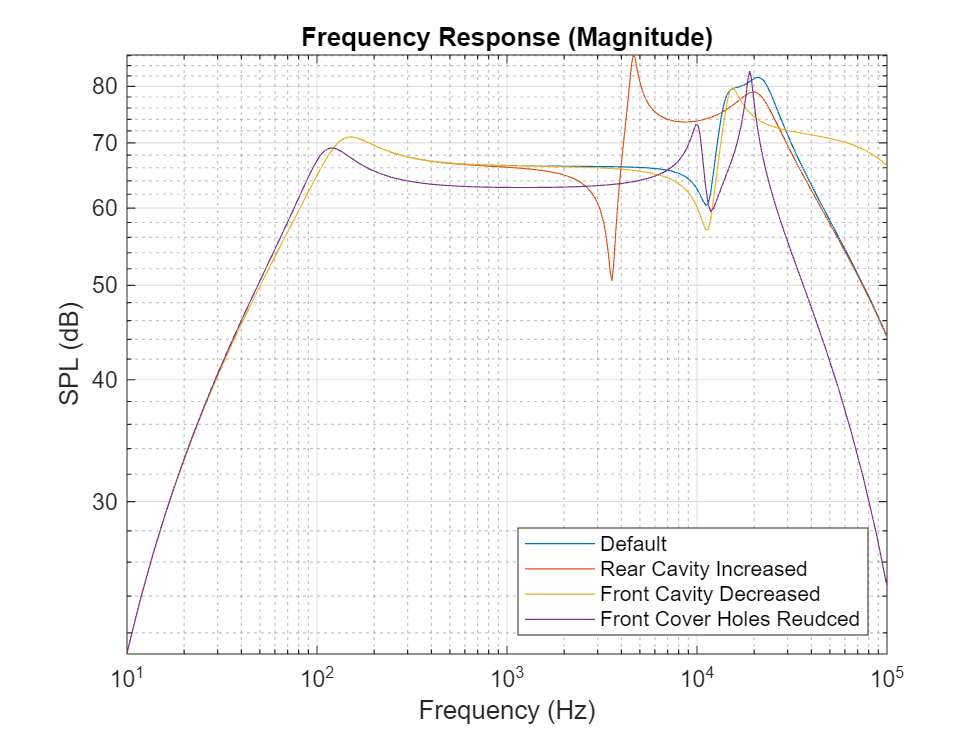

figure(1)
loglog(freq, SPL);
xlim([10 100e3]);
title("Frequency Response (Magnitude)");
xlabel("Frequency (Hz)");
ylabel("SPL (dB)");
legend("Default", "Rear Cavity Increased", "Front Cavity Decreased", "Front Cover Holes Reudced", ...
    "Location", "southeast");
grid on
hold on

Restore the value.

set_param(path1,"m", "17.118");         % set parameter to decrease the rear cavity by a factor of 0.01

## Increase Rear Vent 

Similar to the front cover holes, the rear vents can be modeled as an inductor and resistor connected in series. The inductor and resistor represent the air mass and air resistance inside the small tube respectively. For multiple vents with identical dimensions, they are stacked in parallel. The total air mas and air resistance from the holes can be lumped into single inductor and resistor. The respective values are given by the following equations:


$$M_a =\frac{4\rho l_{\textrm{vents}} }{3A_{\textrm{vents}} N_{\textrm{vents}} }$$



$$R_a =\frac{8\pi \rho \nu l_{\textrm{vents}} }{A_{\textrm{vents}}^2 N_{\textrm{vents}} }$$


where

$l_{\textrm{vents}}$ is the length of the individual vent

$A_{\textrm{vents}}$ is the cross sectional area of the individual vent

$N_{\textrm{vents}}$ is the total number of holes

$\rho$ is the air density

$\nu$ is the kinematic viscosity of air

Both increasing the cross sectional area or the number holes are quivalent to reducing the total air mass contributed by the vents. $A_{\textrm{vents}}$ and $N_{\textrm{vents}}$ are both incersely proportional to the total mass.

Increasing the rear vents is equivalent to opening more rear cavity to the ambient environment, which leads to less stiffness from the rear cavity. This results in increasing the sensitivity of the microspeaker.

path1 = model+"/Mar";
set_param(path1,"m", "190.94/20");         % set parameter to decrease the rear cavity by a factor of 0.01

Linearize the model.

linsys = linearize(model,io);       % linearize model
[mag, ~, wout] = bode(linsys);      % extract results
freq = wout./(2*pi);                % convert radiance to frequency
SPL = 20.*log10(mag(:)./p_ref);     % calculate dBSPL

Plot the results.

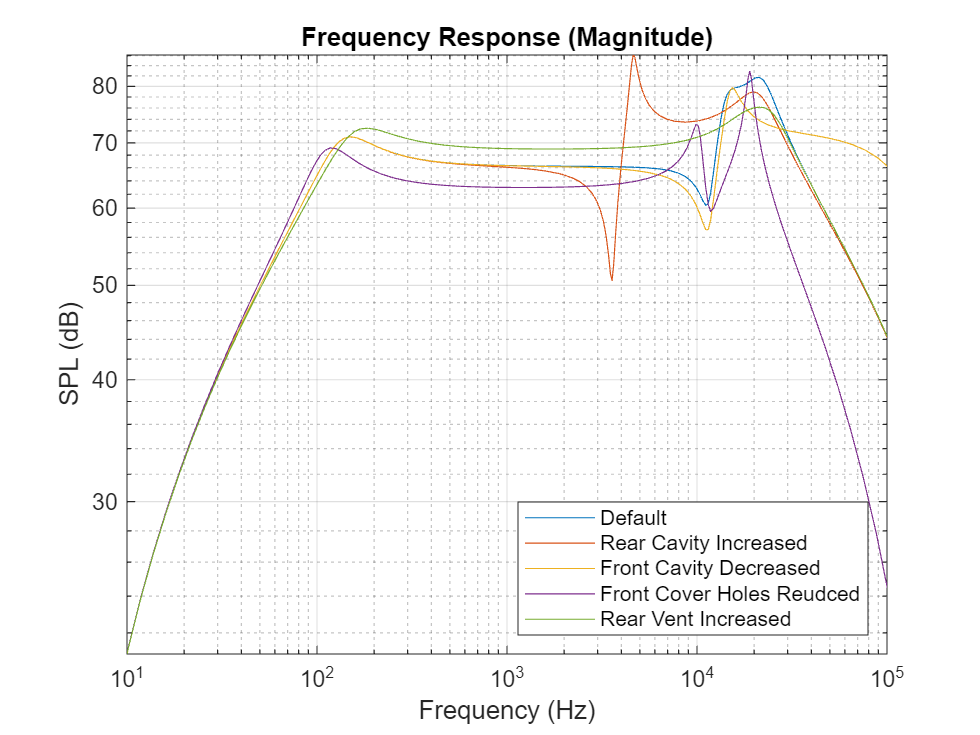

figure(1)
loglog(freq, SPL);
xlim([10 100e3]);
% ylim([70 140]);
title("Frequency Response (Magnitude)");
xlabel("Frequency (Hz)");
ylabel("SPL (dB)");
legend("Default", "Rear Cavity Increased", "Front Cavity Decreased", ...
    "Front Cover Holes Reudced", "Rear Vent Increased", ...
    "Location", "southeast");
grid on
hold on

Restore the value.

set_param(path1,'m', '190.94');         % set parameter to decrease the rear cavity by a factor of 0.01

## Increase Rear Vent Damping

The damping from the rear vent can mostly attribute to the mesh covering the vent opening. A typical microspeaker will have a layer of mesh to smooth out the response, especially the peaks at the system resonance. 

Although reducing the vent cross sectional area and the total number of vents both lead to the increase in air resistance, the effect from the increased air mass usually overpower the contribution from the resistance. To see the individual impact from the air resistance to the overall response, one can treat is as an additional layer of mesh covering the vent opening.

path1 = model+"/Rar";
set_param(path1,"R_r", "1.0194e+06");         % set parameter to decrease the rear cavity by a factor of 0.01

Linearize the model.

linsys = linearize(model,io);       % linearize model
[mag, ~, wout] = bode(linsys);      % extract results
freq = wout./(2*pi);                % convert radiance to frequency
SPL = 20.*log10(mag(:)./p_ref);     % calculate dBSPL

Plot the results.

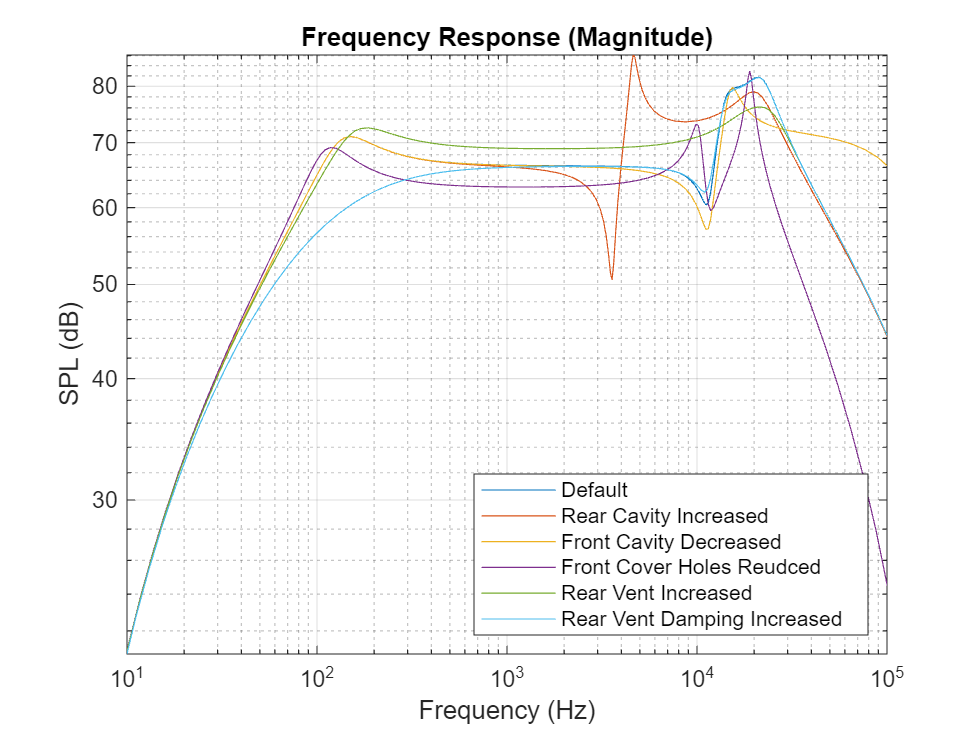

figure(1)
loglog(freq, SPL);
xlim([10 100e3]);
title("Frequency Response (Magnitude)");
xlabel("Frequency (Hz)");
ylabel("SPL (dB)");
legend("Default", "Rear Cavity Increased", "Front Cavity Decreased", ...
    "Front Cover Holes Reudced", "Rear Vent Increased", "Rear Vent Damping Increased",...
    "Location", "southeast");
grid on
hold on

Close the system.

bdclose(model)

## Reference

- Shiah, Y. C. & Her, Hong-Ching & Huang, Jin H. (2008). Parametric Analysis For A Miniature Loudspeaker Used In Cellular Phones. The Journal of Applied Physics. 104. 10.1063/1.3021098. 

- Huang, Jin H. & Her, Hong-Ching & Shiah, Y. C. & Shin, Shaw-Jyh. (2008). Electroacoustic Simulation And Experiment On A Miniature Loudspeaker For Cellular Phones. The Journal of Applied Physics. 103. 10.1063/1.2837112.

*Copyright 2025 The MathWorks, Inc.*